Santeri Saariokari 253345

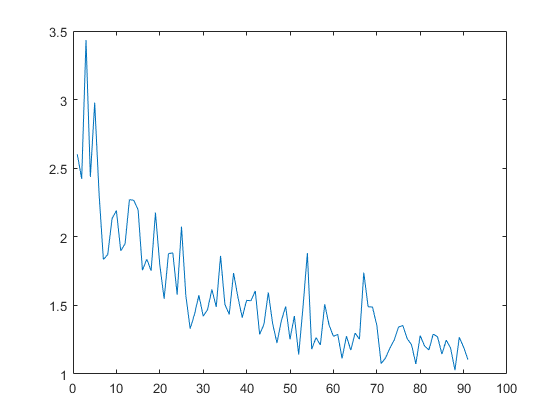

u = eps/2;
left = zeros(1,91);
right = left;
i=1;

for n = 100:10:1000
    A = randi([-10 10], n);
    xe = ones(n,1);
    b = A.*xe;
    x = A\b;
    kappa = cond(A, 'inf');
    left(i) = norm(round(x)-x)/norm(x);
    right(i) = u.*kappa;
    i = i+1;
end

plot(1:length(left),right./left)